T = 10e-3;
reduced_ord_state_obsv;


=== Progetto Osservatore Ridotto ===
Polo osservatore λo = -215.83 rad/s
Guadagno osservatore L  = 182.1037

=== Verifica ===
Autovalore calcolato di Ao: -215.83 (deve essere -215.83)
Dimensioni: Ao(1x1), Bo(1x2), Co(2x1), Do(2x2) ✓



step_gain = 40;

simOut_2_1_2_5_40 = sim('Lab_2\Point_2_1\2_1_2\2_1_2_5\Robust_design_step_validation_2_1_2_5.slx');

Found algebraic loop that contains: 
Robust_design_step_validation_2_1_2_5/State-space controller/MatrixMultiply
Robust_design_step_validation_2_1_2_5/State-space controller/Sum1
Robust_design_step_validation_2_1_2_5/State-space controller/Saturation (discontinuity)
Robust_design_step_validation_2_1_2_5/State-Space
Robust_design_step_validation_2_1_2_5/State-Space


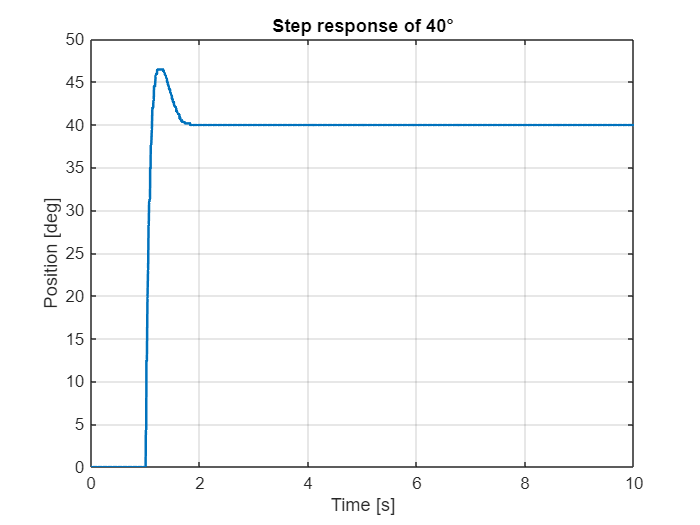


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_1_2_5_40.th.time,squeeze(simOut_2_1_2_5_40.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response of %d°', step_gain));
xlabel('Time [s]');
ylabel('Position [deg]');

% Create plots

step_gain = 70;
simOut_2_1_2_5_70 = sim('Lab_2\Point_2_1\2_1_2\2_1_2_5\Robust_design_step_validation_2_1_2_5.slx');

Found algebraic loop that contains: 
Robust_design_step_validation_2_1_2_5/State-space controller/MatrixMultiply
Robust_design_step_validation_2_1_2_5/State-space controller/Sum1
Robust_design_step_validation_2_1_2_5/State-space controller/Saturation (discontinuity)
Robust_design_step_validation_2_1_2_5/State-Space
Robust_design_step_validation_2_1_2_5/State-Space


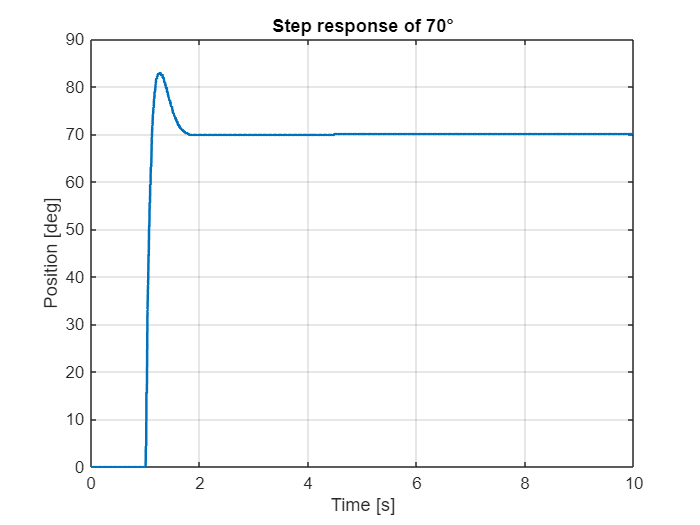


figure; 
plot(simOut_2_1_2_5_70.th.time,squeeze(simOut_2_1_2_5_70.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response of %d°', step_gain));
xlabel('Time [s]');
ylabel('Position [deg]');



step_gain = 120;
simOut_2_1_2_5_120 = sim('Lab_2\Point_2_1\2_1_2\2_1_2_5\Robust_design_step_validation_2_1_2_5.slx');

Found algebraic loop that contains: 
Robust_design_step_validation_2_1_2_5/State-space controller/MatrixMultiply
Robust_design_step_validation_2_1_2_5/State-space controller/Sum1
Robust_design_step_validation_2_1_2_5/State-space controller/Saturation (discontinuity)
Robust_design_step_validation_2_1_2_5/State-Space
Robust_design_step_validation_2_1_2_5/State-Space


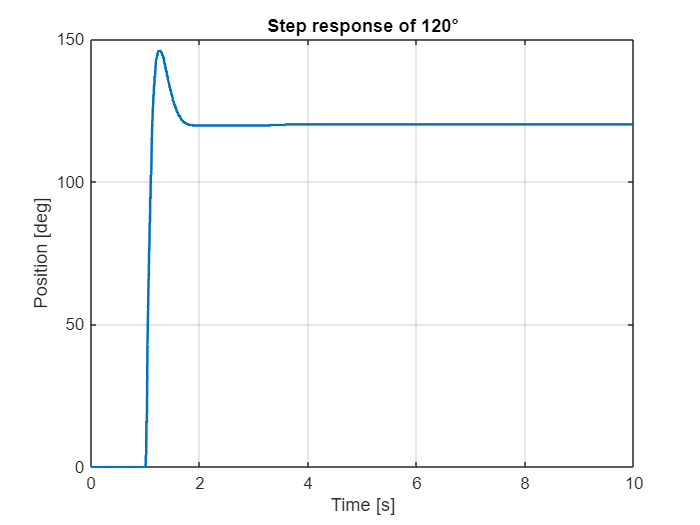


figure; 
plot(simOut_2_1_2_5_120.th.time,squeeze(simOut_2_1_2_5_120.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response of %d°', step_gain));
xlabel('Time [s]');
ylabel('Position [deg]');